# **Explore 1-DOF Spring Mass Damper           **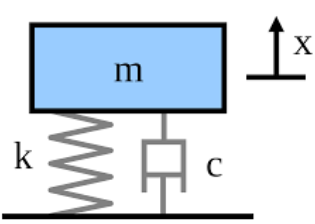

In this example we're going to study the single degree of freedom (dof)  mechanical system known as the "Spring Mass Damper".  There are 3 parameters for this 1-dof mechanical system:

$\qquad \bullet $ **m** is the spring mass (kg)

$\qquad 
\bullet $ **k** is the spring stiffness (N/m)

$\qquad 
\bullet $ **c** is the spring damping (N/(m/sec))  

In this tutorial we're going to look at the following subtopics:

$\qquad \bullet
$ derive the **ANALYTICAL** solution for the ZERO excitation case

$\qquad \bullet $ derive the **ANALYTICAL** solution for an excitation force made up of a STEP function type input.

$\qquad \bullet
$ run a series of simulations with the **ANALYTICAL** where we change the value of the damping for each run

$\qquad \bullet $ derive the **NUMERICAL**  solution for an excitation force made up of a STEP function type input.

Finally we'll recommend that you explore the corresponding models developed in:

$\bullet $  Simulink,  and 

$\bullet $  Simscape.

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

**Apply Newton's law:**

To derive the system's equation of motion, we assume that the system is in motion with positive displacement and velocity, and we then construct a free body diagram that shows all of the forces acting on the mass. This free body diagram looks like this:

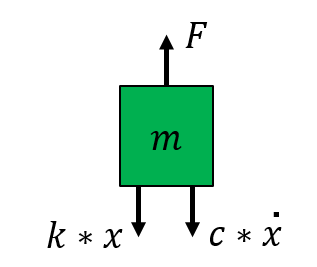

From this diagram we then apply Newton's law:  $m\thinspace\ddot{x} = \Sigma \enspace Forces$ .   

So for our system we would have:


$$m\thinspace.\thinspace\ddot{x}(t) = F -c \thinspace.\thinspace \dot{x}(t) - k \thinspace.\thinspace x(t)$$


Which can then be rearranged into the following form:


$$m\thinspace\ddot{x}(t) + c \thinspace.\thinspace\dot{x}(t) + k \thinspace.\thinspace x(t) = F$$


The above 2nd order Ordinary Differential Equation (ODE) is referred to as the systems equation of motion. Our next step is to find the analytical solution to this 1-dof system.  This is a good exercise to do by hand.  To confirm your hand derived solution, let's get the ***Symbolic toolbox*** for MATLAB to solve it too !

We'll do this in two stages, first we'll look at the homogeneous case, ie: the case where there are NO excitation forces. Then we'll also solve the case where we do have some excitation forces - and specifically we'll look at STEP type input forces.

**Define the Mechanical system parameters:**

m = 1       % (kg)

m = 1

c = 2*0.2*3 % (N/(m/sec))

c = 1.2000

k = 9       % (N/m)

k = 9

**Define the system INITIAL conditions**

% define some INITIAL conditions
init_x    = 1;
init_xdot = 0;

**Find the analytical solution to the 2nd order ODE:    Explore the ZERO excitation case**

Recall the ODE that we need to solve:  $m\thinspace\ddot{x}(t) + c \thinspace.\thinspace\dot{x}(t) + k \thinspace.\thinspace x(t) = F$

% define some SYMBOLIC variables 
syms t x(t)

% our excitation force
f  = 0;       

Construct our ODE:  $m\thinspace\ddot{x}(t) + c \thinspace.\thinspace\dot{x}(t) + k \thinspace.\thinspace x(t) = F$

% construct the SYMBOLIC 2nd order ODE 
dx = diff(x);
EQ = m*diff(x,2) + c*diff(x,1) + k*x == f; 


Now find the analytical solution applying our IC's

x = dsolve( EQ,   x(0)==init_x,    ...
                 dx(0)==init_xdot, ...
                 'IgnoreAnalyticConstraints',false)

$$x = {\mathrm{e}}^{-\frac{3\,t}{5}}\,\cos\left(\frac{6\,\sqrt{6}\,t}{5}\right)+\frac{\sqrt{6}\,{\mathrm{e}}^{-\frac{3\,t}{5}}\,\sin\left(\frac{6\,\sqrt{6}\,t}{5}\right)}{12}$$

Because we can, compute the velocity of the mass:

v = diff(x,t)                 

$$v = -\frac{5\,\sqrt{6}\,{\mathrm{e}}^{-\frac{3\,t}{5}}\,\sin\left(\frac{6\,\sqrt{6}\,t}{5}\right)}{4}$$

Plot the solution:

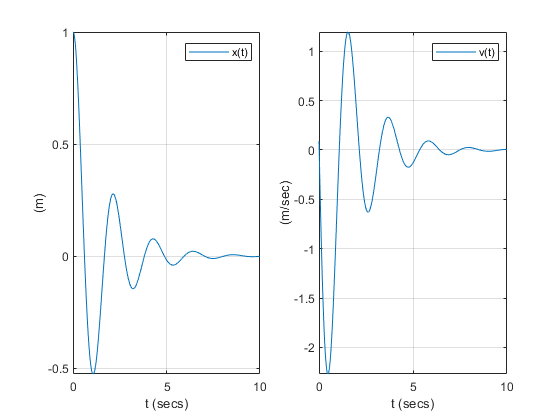

figure;

subplot(1,2,1)
   fplot(x, [-0.01, 10]);
   xlabel('t (secs)'); ylabel('(m)'); grid('on'); legend('x(t)')
subplot(1,2,2)
   fplot(v, [-0.01, 10]);
   xlabel('t (secs)'); ylabel('(m/sec)'); grid('on');   legend('v(t)')

**Let's do a few "warm up" stretches:**

In the next example, we'll consider the case of the system being excited by a STEP type input force.  So let's do a quick review of the HEAVISIDE step function.

In the example below we're applying a 2 second delay to the input signal, ie: the step occurs at t=2 seconds. Note also that the magnitude of the STEP function is 6.

clear t f(t) s 
syms  t f(t) s 
h = 6*heaviside(t-2)

$$h = 6\,\mathrm{heaviside}\left(t-2\right)$$

And just to make sure - here's  a plot of it:

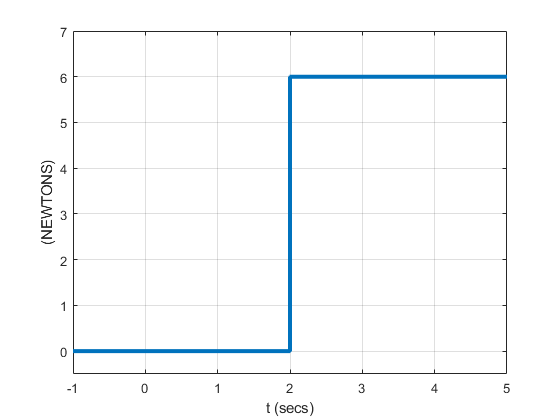

figure;   fplot(h, [-1, 5], 'LineWidth', 3)
xlabel('t (secs)'); ylabel('(NEWTONS)'); grid('on');
ylim([-0.5 7])

And just because we "can", you probably remember what the Laplace Transform of this is:

laplace(h,s)

$$ans = \frac{6\,{\mathrm{e}}^{-2\,s}}{s}$$

OK:  it's time to get back to the spring mass damper example.

**Find the analytical solution to the 2nd order ODE:    Explore an excitation case involing a STEP type function**

Recall the ODE that we need to solve:  $m\thinspace\ddot{x}(t) + c \thinspace.\thinspace\dot{x}(t) + k \thinspace.\thinspace x(t) = F$.  In this next example we'll look at the systems response to a STEP type input force. Our F(t) will be:

- $F\left(t\right)=3\ldotp u\left(t-15\right)$   where u(t) is the UNIT STEP function (aka the HEAVISIDE function)

clear x f t v

% define some SYMBOLIC variables
syms t f x(t)

% here is our STEP function
% we're applying a 15 seconds delay and the STEP magnitude is 3 
f  = 3*heaviside(t-15);

% construct the SYMBOLIC 2nd order ODE 
dx = diff(x);
EQ = m*diff(x,2) + c*diff(x,1) + k*x == f;

% now find the analytical solution applying our IC's
x = dsolve( EQ,   x(0)==init_x,    ...
                 dx(0)==init_xdot, ...
                 'IgnoreAnalyticConstraints',false);
simplify(x)

$$ans = \begin{array}{l} \frac{\mathrm{heaviside}\left(t-15\right)}{3}+\sigma_{1}\,\cos\left(\sigma_{2}\right)+\frac{\sqrt{6}\,\sigma_{1}\,\sin\left(\sigma_{2}\right)}{12}-\frac{\mathrm{heaviside}\left(t-15\right)\,\sigma_{1}\,{\mathrm{e}}^{9}\,\cos\left(\sigma_{2}-18\,\sqrt{6}\right)}{3}-\frac{\sqrt{6}\,\mathrm{heaviside}\left(t-15\right)\,\sigma_{1}\,{\mathrm{e}}^{9}\,\sin\left(\sigma_{2}-18\,\sqrt{6}\right)}{36}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{3\,t}{5}}\\ \sigma_{2}=\frac{6\,\sqrt{6}\,t}{5} \end{array}$$

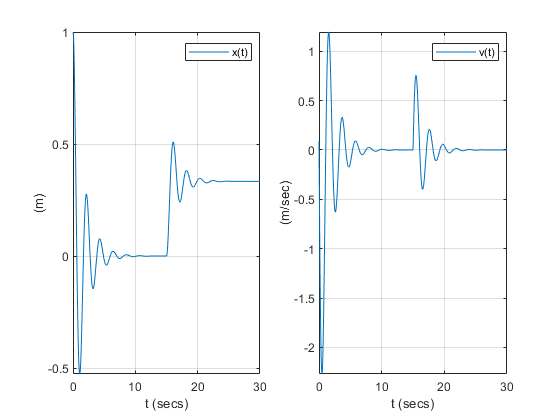

% compute the velocity (because we can)
v = diff(x,t);

% and plot x and v
figure;

subplot(1,2,1)
   fplot(x, [-0.01, 30]);
   xlabel('t (secs)'); ylabel('(m)'); grid('on'); legend('x(t)');
subplot(1,2,2)
   fplot(v, [-0.01, 30]);
   xlabel('t (secs)'); ylabel('(m/sec)'); grid('on'); legend('v(t)');

   
% Save this STEP respose solution for later comparison
x_ana_step_sol = x;

**Cool to know:** We can convert a symbolic expression into a MATLAB function

x_func_hand = matlabFunction(x)

x_func_hand = function_handle with value:
    @(t)exp(t.*(-3.0./5.0)).*cos(sqrt(6.0).*t.*(6.0./5.0))+sqrt(6.0).*exp(t.*(-3.0./5.0)).*sin(sqrt(6.0).*t.*(6.0./5.0)).*(1.0./1.2e1)+exp(t.*(-3.0./5.0)).*cos(sqrt(6.0).*t.*(6.0./5.0)).*(heaviside(t-1.5e1).*exp(t.*(3.0./5.0)).*(cos(sqrt(6.0).*t.*(6.0./5.0)).*1.2e1-sqrt(6.0).*sin(sqrt(6.0).*t.*(6.0./5.0))).*(1.0./3.6e1)-heaviside(t-1.5e1).*exp(9.0).*(cos(sqrt(6.0).*1.8e1).*1.2e1-sqrt(6.0).*sin(sqrt(6.0).*1.8e1)).*(1.0./3.6e1))+exp(t.*(-3.0./5.0)).*sin(sqrt(6.0).*t.*(6.0./5.0)).*(heaviside(t-1.5e1).*exp(t.*(3.0./5.0)).*(sin(sqrt(6.0).*t.*(6.0./5.0)).*1.2e1+sqrt(6.0).*cos(sqrt(6.0).*t.*(6.0./5.0))).*(1.0./3.6e1)-heaviside(t-1.5e1).*exp(9.0).*(sin(sqrt(6.0).*1.8e1).*1.2e1+sqrt(6.0).*cos(sqrt(6.0).*1.8e1)).*(1.0./3.6e1))


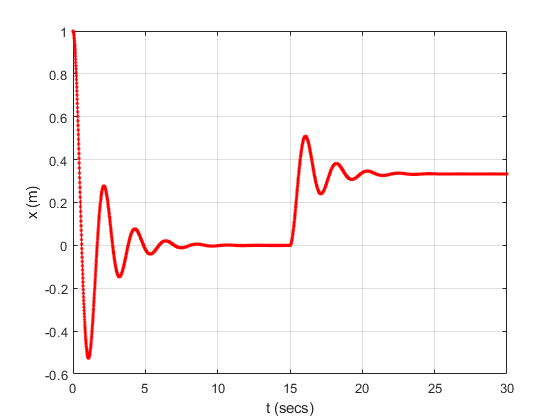

   
t_vec = 0:0.01:30;
x_vec = x_func_hand( t_vec );

figure;
plot(t_vec, x_vec, 'r.-');
xlabel('t (secs)'); ylabel('x (m)'); grid('on');

## Let's finish off with a parameter sweep on damping for the HOMOGENEOUS case

So in this example we're going to solve our ODE for different values of damping. Recall the ODE that we need to solve:  $m\thinspace\ddot{x}(t) + c \thinspace.\thinspace\dot{x}(t) + k \thinspace.\thinspace x(t) = F$

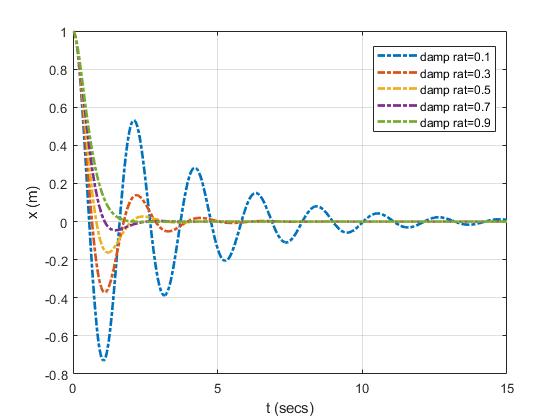

t_vec   = 0:0.01:15;
X_mat   = [];
leg_str = {};
for damp_rat = 0.1: 0.2: 1
    % clear any previous solution  
    clear x f t  
    syms t x(t)
    
    % define damping value
    c_val = 2*3*damp_rat; 
    
    % construct the SYMBOLIC 2nd order ODE 
    f  = 0;       
    dx = diff(x);
    EQ = m*diff(x,2) + c_val*diff(x,1) + k*x == f;
    
    % now find the analytical solution applying our IC's
    x = dsolve( EQ, x(0)==init_x,    ...
                   dx(0)==init_xdot, ...
                 'IgnoreAnalyticConstraints',false);
             
    x_fh_hand = matlabFunction(x);
    
    X_mat     = [X_mat;   x_fh_hand(t_vec)];
    
    leg_str   = [leg_str; {sprintf('damp rat=%.1f',damp_rat)} ];
end
  

figure;
plot(t_vec, X_mat, '-.', 'LineWidth', 2);
xlabel('t (secs)'); ylabel('x (m)'); grid('on');
legend(leg_str, 'Location', 'Best')

# Numerical solution:

So far we've looked at finding an analytical solution to the mechanical 1-dof system. An alternate approach is to solve the problem numerically. This numerical approach is extremely attractive when an analytical solution becomes difficult and/or impossible to derive.  At the heart of this approach are MATLAB's ODE solver suite - MATLAB has many ODE solver algorithms.  A good general purpose solver is the MATLAB function `ode45()` .

These numeric ODE solvers require you to package your problem into a 1st order form. We'll discuss how to do this in more detail in the next tutorial (on 2-dof systems), but for the moment here's a quick summary of the form that we need to package our problem into.  We consider the general *n-dof* case:  $M \ddot{X} + C\dot{X} + KX = F$  where $X \in R^{n\times1}$

And then we repackage it into this form:

                      $\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$\times \pmatrix{
\dot{X} \cr
X \cr
}$  +  $\pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$

which we can abbreviate to:

                  $\dot{Z} = A \times Z + G$    where:  

- $Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   and    $G = \pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$    and    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{n \times n} & 0_{n \times n} \cr
}$

So the new 1st order system described above, is the form that we can now send to MATLAB's Numerical ODE solver suite. Let's look at an example. Specifically we'll look at the systems response to a STEP type input force. Specifically, our F9t) will be:

- $F\left(t\right)=3\ldotp u\left(t-15\right)$   where u(t) is the UNIT STEP function (aka the HEAVISIDE function)

% Define your INITIAL conditions
z_init = [ init_xdot ;
           init_x    ;  ];

% define the system EXCITATION functions
F = @(t) 3*heaviside(t-15);

% define the 1st order system to solve
A = [-c/m, -k/m;  
        1,   0];
    
G = @(t) ([F(t)/m;
            0]);    
        
MY_SYSTEM = @(t, z) (A*z + G(t));

% Define some ODE solver settings
t_span     = [0 20];
my_options = odeset('RelTol', 1e-7, 'AbsTol', 1e-7);

% use ODE45 to numerically solve your system
%[T,Y] = solver(odefun,   tspan,  z0,     options)
[T,Z]  = ode45(MY_SYSTEM, t_span, z_init, my_options);


## Plot the NUMERIC solution:

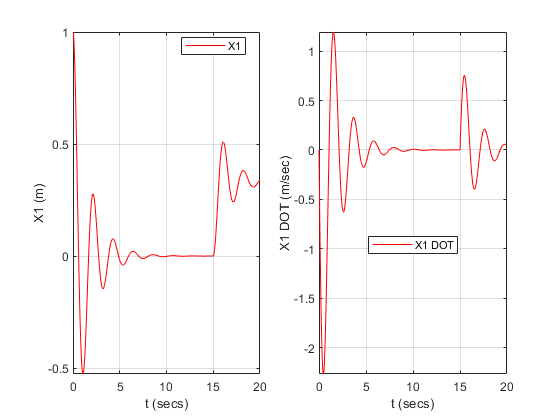

X1_dot = Z(:,1); 
X1     = Z(:,2);  

figure;
subplot(1,2,1);
   plot(T,X1,'-r');      xlabel('t (secs)'); ylabel('X1 (m)'); grid('on'); axis('tight');
                         legend('X1', 'Location', 'best');
   %----------------------------------------------------------------------- 
subplot(1,2,2);
   plot(T,X1_dot,'-r');  
                         xlabel('t (secs)'); ylabel('X1 DOT (m/sec)'); grid('on'); axis('tight');
                         legend('X1 DOT', 'Location', 'best');

# **Compare ANALYTICAL versus Numeric solutions**

**We 'll just do a visual comparison for now:**

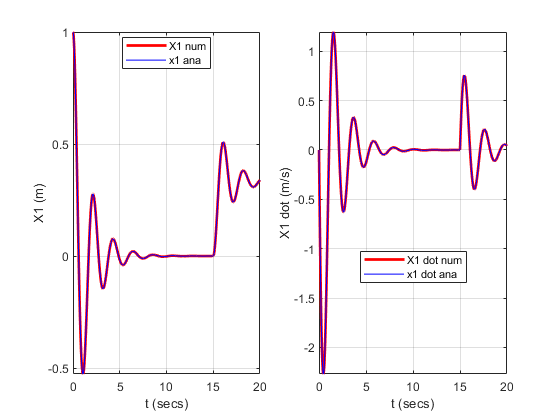

figure;
subplot(1,2,1);
    plot(T,X1,'-r', 'Linewidth', 2);   hold on     
   fplot(x_ana_step_sol, [0, 20], '-b');
   
                         xlabel('t (secs)'); ylabel('X1 (m)'); grid('on'); axis('tight');
                         legend({'X1 num', 'x1 ana'}, 'Location','best');
   %----------------------------------------------------------------------- 
subplot(1,2,2);
    plot(T,X1_dot,'-r', 'Linewidth', 2); hold on
   fplot( diff(x_ana_step_sol), [0, 20], '-b')
   
                         xlabel('t (secs)'); ylabel('X1 dot (m/s)'); grid('on'); axis('tight');
                         legend({'X1 dot num', 'x1 dot ana'}, 'Location','best');                            

# Next steps - part 1

If you found this tutorial on MATLAB interesting, have a look at the Simulink model called **bh_1dof_hello.slx**.  This model shows how Simulink and Simscape can be used to model and solve the same spring mass damper system ... but instead of writing lines of code, Simulink models are built using block diagrams.

In **Simulink**, here's how we model the ODE for the spring mass damper.  Note how we have 2 integrators which integrate from $\ddot{X} \rightarrow \dot{X}$ and then from $\dot{X} \rightarrow X$.  These integrators can be initialised by the system's initial conditions.

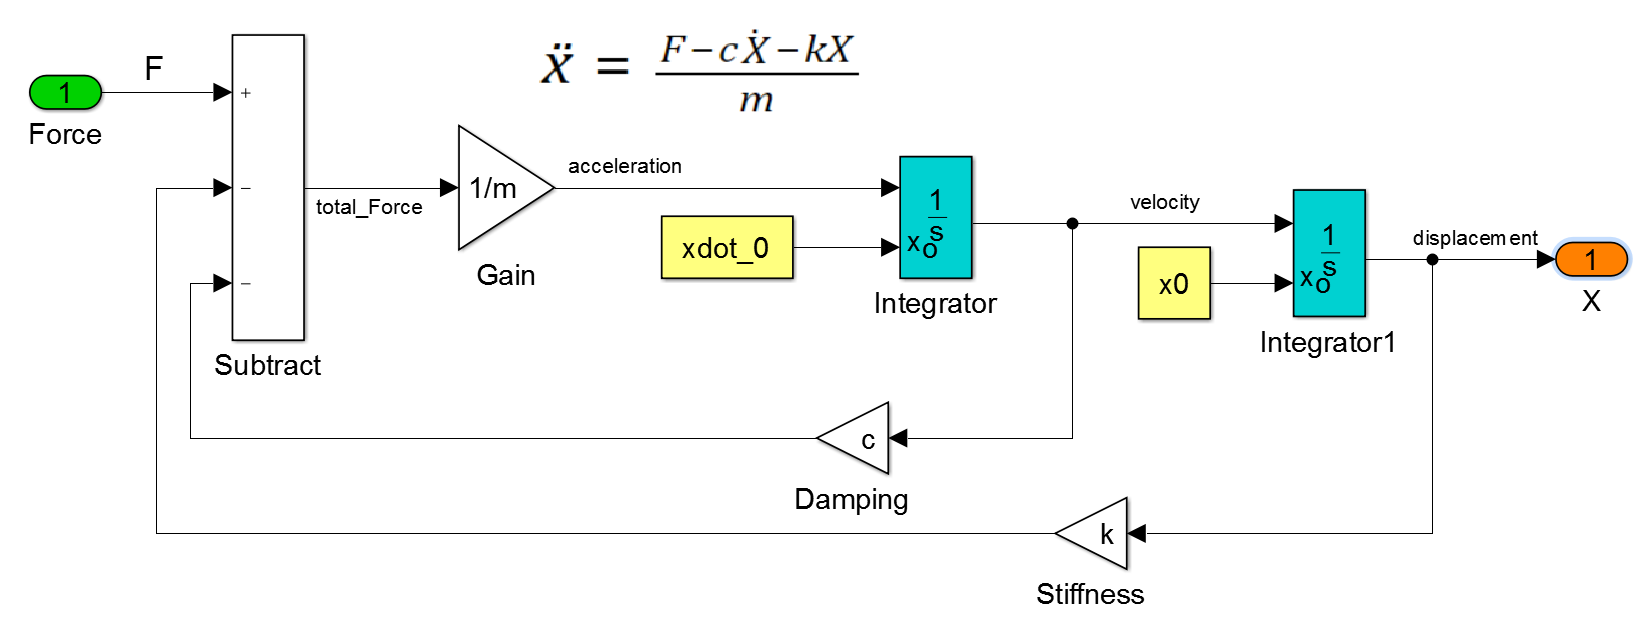

While in **Simscape**(which is still within the Simulink modelling environment), the spring mass damper model looks like this:

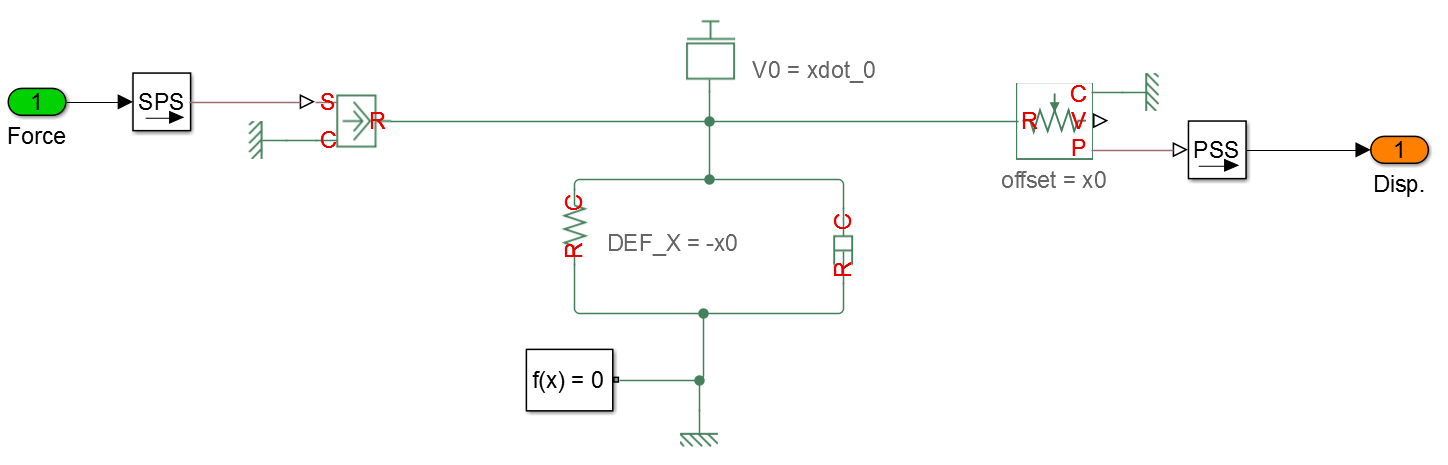

When you simulate these SIMULINK models, here's an example of a "scope" block that shows the excitation force *F(t)* and the spring's displacement *X(t):*